## Qdots in PAAm at 389fps

To run *and* export, paste the following command. Otherwise, export manually. You must first define monkier to do this.

% export("TrackMate_Live_Script_guide.mlx", strcat('C:\Users\al3xm\Documents\GitHub\HISTia\TrackMate Reports\',monkier), HideCode=false, OpenExportedFile=true, Run=true,FigureResolution=1600)

Name this data analysis run

tic()
monkier = '300fps Qdots In PAAm March 13 Dataset VanHove BigTau v2';
disp(monkier)

300fps Qdots In PAAm March 13 Dataset VanHove BigTau


Set the current directory for data saving purposes.

cd('C:\Users\al3xm\Documents\GitHub\HISTia')

This Report generated at

disp(datetime)

   02-Apr-2025 18:51:09



Define the source folder here:

main_folder =  "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks"

main_folder = "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks"

paths =  FileFinder(main_folder, '.xml')

paths = 1×36 string array
    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_31.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_32.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_33.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_34.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_35.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_36.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeriesQT3_QDOTS_IN_PAG_388fps_11_Tracks_37.xml"    "C:\Users\al3xm\Documents\_Local_Data\25.03.12_PAG_HILO_Beads\2.5msTracks\tSeries_BEADS_

if ~isfolder(main_folder)
    error('please enter a valid directory')
elseif isempty(paths)
    error('please ensure the folder contains .xml ParticleTrack exports')
end

If you want to scale the tracks, set the scaling factor here in pixels/distance unit. Otherwise, set scaling to -1 to avoid scaling.

scaling = 1 % units per input unit

scaling = 1

Define the units

SpaceUnits = 'microns';
TimeUnits = 'seconds';

Enter the timestep **in time units. Ensure that you use the inverse of the fps, not exposure.**

dt=0.0026 % 1/(fps)

dt = 0.0026

what is the minimum track length you want to consider?

MinTrackLength = 5

MinTrackLength = 5

Now, generate the MSD analyzer structure. Note that this filters out any tracks with a track length of less than 7 by default, though this can be changed.

ma1 = TrackMateImport(main_folder, true, MinTrackLength, scaling);

found 1280 tracks in the file.
found 1106 tracks in the file.
found 1037 tracks in the file.
found 985 tracks in the file.
found 1086 tracks in the file.
found 892 tracks in the file.
found 877 tracks in the file.
found 1336 tracks in the file.
found 2179 tracks in the file.
found 1768 tracks in the file.
found 1929 tracks in the file.
found 1752 tracks in the file.
found 1441 tracks in the file.
found 1425 tracks in the file.
found 1479 tracks in the file.
found 1431 tracks in the file.
found 1540 tracks in the file.
found 1288 tracks in the file.
found 1422 tracks in the file.
found 996 tracks in the file.
found 1288 tracks in the file.
found 1180 tracks in the file.
found 1027 tracks in the file.
found 900 tracks in the file.
found 898 tracks in the file.
found 926 tracks in the file.
found 853 tracks in the file.
found 1001 tracks in the file.
found 1270 tracks in the file.
found 1055 tracks in the file.
found 1518 tracks in the file.
found 1425 tracks in the file.
found 1415 track

Computing MSD of 26938 tracks... 26Done.


ma1 =ma1.fitMSD(0.5); % set to short clipping factor to find diffusive rate

Fitting 26938 curves of MSD = f(t), taking only the first 50% of each curve... 26Done.


ma1 = ma1.fitLogLogMSD(0.5); % set to long clipping factor for linearity measure

Fitting 26938 curves of log(MSD) = f(log(t)), taking only the first 50% of each curve... Done.


d_est = mean(ma1.lfit.a) * (1/dt); % starts with units^2 per frame, divide by frames/time unit.
% This gives the estimated slope of the MSD in units^2/second
gamma_est = mean(ma1.loglogfit.alpha); % Gives time scaling factor of the MSD.
dimensionality_modifier = 4; % Conversion to use conventional x^2 = 4Dt metric for 2D diffusion.
fprintf(strcat("The diffusion coefficient is D=", string(d_est/(dimensionality_modifier)), ' ', SpaceUnits, '^2/', TimeUnits));

The diffusion coefficient is D=5.7047microns^2/seconds

% fprintf(strcat("The time scaling factor is gamma=", string(gamma_est), '.'));

Now, we plot the MSD. If you want to plot an expected value, set it. Otherwise, set D to -1.

D_expect=14.4; %D=0.4292 for 1um beads in water.
fprintf(strcat('excpected diffusion coefficient: ', string(D_expect),' (', SpaceUnits, ')^2/', TimeUnits))

excpected diffusion coefficient:14.4 (microns)^2/seconds

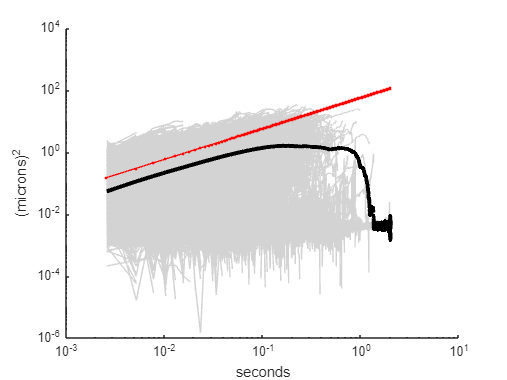

ans = 1.0e+04 *

         0         0         0    1.1406         0
    0.0000    0.0000    0.0000    1.0079    0.0000
    0.0000    0.0000    0.0000    0.8622    0.0000
    0.0000    0.0000    0.0000    0.7770    0.0000
    0.0000    0.0000    0.0000    0.7150    0.0001
    0.0000    0.0000    0.0000    0.6569    0.0001
    0.0000    0.0000    0.0000    0.6114    0.0001
    0.0000    0.0000    0.0000    0.5707    0.0001
    0.0000    0.0000    0.0000    0.5290    0.0001
    0.0000    0.0000    0.0000    0.4879    0.0001


FigMeanMSD(SpaceUnits, TimeUnits,ma1, dt,D_expect,true)

Now  we create a plot of the mean velocity correlation as a function of time.

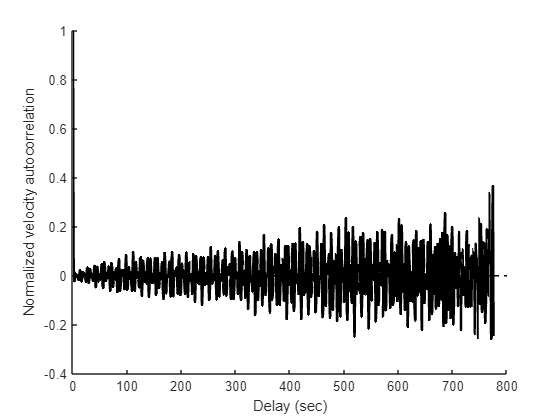

Computing velocity autocorrelation of 26938 tracks...                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   

figure;
ma1.plotMeanVCorr;

We may also directly compute velocities and plot them as a historgram

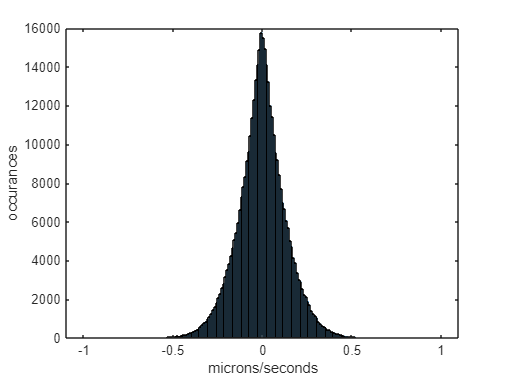

v = ma1.getVelocities;
V=vertcat(v{:});
edges2 = -1:0.01:1;
histogram(V(:,2),edges2)
xlabel(strcat(SpaceUnits, '/', TimeUnits))
ylabel("occurances")

Now, we must call CenterTracks.

CenterTracks=CreateCenterTracks(ma1.tracks);

We may now create a short vs long track diagram.

figure();
% UniDomainFigCenterJuxt(SpaceUnits, CenterTracks, 10,10, 10, 10, true, true, 1)

Now create a VanHovePlot. This function calls the new VanHove2.m so it is relatively fast and creates bins with equal widths, but it can still take a while to run.

Now, we can can manimputme the CreateVanHovePlots function in a few ways. 

We can change the time steps, the number of particles assigned to each bin, and the minimum bin width.

The BinSize determines the number of particles which the Van

BinSize = 10

BinSize = 10

MinBin = 0.05 % In microns. I don't recommend going much below diffraction limit/4

MinBin = 0.0500

VanHoveStats= CreateVanHovePlots(SpaceUnits, TimeUnits, ma1.tracks, BinSize, [1:50], main_folder, MinBin, dt)


 Calculating VanHove Distribution dt=1

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=2

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=3

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=4

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=5

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=6

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=7

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=8

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=9

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=10

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=11

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=12

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=13

5000
10000
15000
20000
25000
 Calculating VanHove Distribution dt=14

5000
10000
15000
20000
25000
 Calculating VanHove Distrib

Sorting dt=2 into bins 
Sorting dt=3 into bins 
Sorting dt=4 into bins 
Sorting dt=5 into bins 
Sorting dt=6 into bins 
Sorting dt=7 into bins 
Sorting dt=8 into bins 
Sorting dt=9 into bins 
Sorting dt=10 into bins 
Sorting dt=11 into bins 


Sorting dt=12 into bins 
Sorting dt=13 into bins 
Sorting dt=14 into bins 
Sorting dt=15 into bins 
Sorting dt=16 into bins 
Sorting dt=17 into bins 


Sorting dt=18 into bins 
Sorting dt=19 into bins 
Sorting dt=20 into bins 
Sorting dt=21 into bins 
Sorting dt=22 into bins 
Sorting dt=23 into bins 
Sorting dt=24 into bins 
Sorting dt=25 into bins 
Sorting dt=26 into bins 
Sorting dt=27 into bins 
Sorting dt=28 into bins 
Sorting dt=29 into bins 
Sorting dt=30 into bins 
Sorting dt=31 into bins 
Sorting dt=32 into bins 
Sorting dt=33 into bins 
Sorting dt=34 into bins 
Sorting dt=35 into bins 


Sorting dt=36 into bins 


Sorting dt=37 into bins 
Sorting dt=38 into bins 
Sorting dt=39 into bins 
Sorting dt=40 into bins 
Sorting dt=41 into bins 
Sorting dt=42 into bins 
Sorting dt=43 into bins 
Sorting dt=44 into bins 
Sorting dt=45 into bins 
Sorting dt=46 into bins 
Sorting dt=47 into bins 
Sorting dt=48 into bins 
Sorting dt=49 into bins 
Sorting dt=50 into bins 


VanHoveStats = struct with fields:
             Data: {50×1 cell}
      CenterPoint: {50×1 cell}
         EquiProb: {50×1 cell}
    TotStepsCount: [50×2 table]
          BinSize: 10
              tau: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50]
        FrameTime: 0.0026
           MinBin: 0.0500
       SpaceUnits: 'microns'
        TimeUnits: 'seconds'


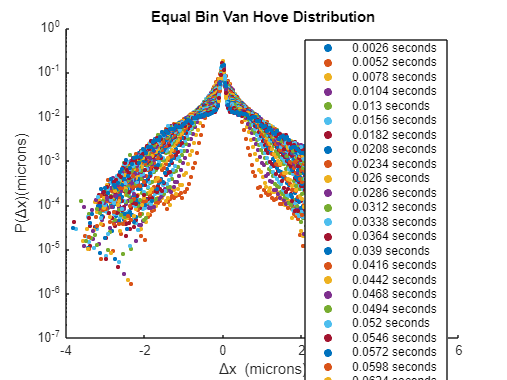

PlotVanHove(SpaceUnits, TimeUnits, VanHoveStats.CenterPoint, VanHoveStats.EquiProb, VanHoveStats.tau, 10, dt);

Save the data in SuperStruct format to the SuperStructs Github folder.

MasterSaveD(monkier,dt, ma1,main_folder, MinTrackLength, SpaceUnits, TimeUnits, VanHoveStats, cd)

ans = "C:\Users\al3xm\Documents\GitHub\HISTia\SuperStructs\300fps Qdots In PAAm March 13 Dataset VanHove BigTau2025-04-02.19.01.58.mat"

Save this output as a pdf for later viewing.

toc()

Elapsed time is 660.998495 seconds.
